# Part 6 A

Ts = 10e-9; % Symbol duration, s
f0 = 1.0e9; % Carrier frequency, Hz
SNR = 0:0.5:15; % SNR, dB
mF = 4; % Frequency shift keying index

% Generate binary data randomly
N = 1e5; % Number of bits to be sent
sB = randi(2, 1, N) - 1; % Random generated data signal, row vector, 1xN

% Generate Carrier signal
L = 200; % The number of samples per symbol
dT = Ts/L; % Time step
t = 0:dT:Ts-dT; % Time interval for one symbol
s0 = sin(2*pi*f0*t); % Carrier signal 
Eb = sum(s0.^2); % Energy for one symbol
SNRval = 8.9; % SNR in course project

% BASK modulation
sTx = kron(sB, s0);

% Generate Noise power
EbN0 = 10.^(SNR/10); % Linear SNR 
N0 = Eb./EbN0; % Noise spectral power density
sigma = sqrt(N0/2); % StDev of Noise

for k = 1:length(SNR)
    sNoise = sigma(k)*randn(1, N*L); % Noise in AWGN channel
    sRx = sTx + sNoise; % Add noise in transmitted signal
    % Perform correlator receiver of noisy signal
    sRxMtx = reshape(sRx, L, N); % Slice received signal into segments in each column BASK
    demMt = s0 * sRxMtx > Eb/2; % Optimal correlator receiver, BASK demodulate, matrix format 
    NumErr = sum(demMt ~= sB); % Calculate number of errors
    BERval(k) = NumErr / N; % BER value estimation
    fprintf('BASK: SNR: %f, BER: %f\n', SNR(k), BERval(k));
    
end

BASK: SNR: 0.000000, BER: 0.238520
BASK: SNR: 0.500000, BER: 0.228230
BASK: SNR: 1.000000, BER: 0.211150
BASK: SNR: 1.500000, BER: 0.198350
BASK: SNR: 2.000000, BER: 0.186100
BASK: SNR: 2.500000, BER: 0.174890
BASK: SNR: 3.000000, BER: 0.157840
BASK: SNR: 3.500000, BER: 0.144210
BASK: SNR: 4.000000, BER: 0.131330
BASK: SNR: 4.500000, BER: 0.118100
BASK: SNR: 5.000000, BER: 0.106350
BASK: SNR: 5.500000, BER: 0.090500
BASK: SNR: 6.000000, BER: 0.077020
BASK: SNR: 6.500000, BER: 0.067180
BASK: SNR: 7.000000, BER: 0.055870
BASK: SNR: 7.500000, BER: 0.046680
BASK: SNR: 8.000000, BER: 0.036860
BASK: SNR: 8.500000, BER: 0.030280
BASK: SNR: 9.000000, BER: 0.022690
BASK: SNR: 9.500000, BER: 0.017570
BASK: SNR: 10.000000, BER: 0.012260
BASK: SNR: 10.500000, BER: 0.008370
BASK: SNR: 11.000000, BER: 0.006060
BASK: SNR: 11.500000, BER: 0.003930
BASK: SNR: 12.000000, BER: 0.002450
BASK: SNR: 12.500000, BER: 0.001320
BASK: SNR: 13.000000, BER: 0.000930
BASK: SNR: 13.500000, BER: 0.000530
BASK: SNR: 1

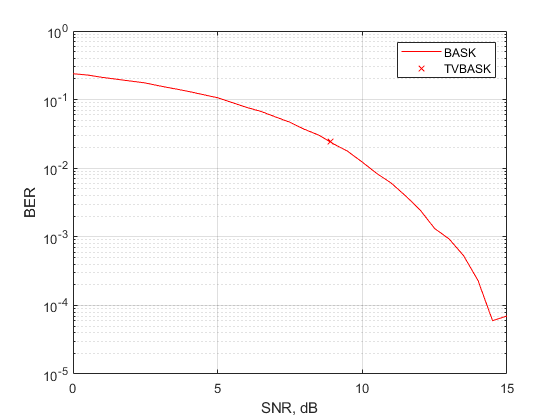


EbN1 = 10^(SNRval/10);
x = sqrt(EbN1/2); % BASK
Perr = 1 - 1/2*(1+erf(x/sqrt(2))); % Error Probability for BASK

figure(1)
semilogy(SNR, BERval, 'r');
grid on;
xlabel('SNR, dB');
ylabel('BER');
hold on;
semilogy(SNRval, Perr, 'rx');
legend('BASK', 'TVBASK');

# PART 6 B

Ts = 10e-9; % Symbol duration, s
f0 = 1.0e9; % Carrier frequency, Hz
SNR = 0:0.5:15; % SNR, dB
mF = 4; % Frequency shift keying index

% Error Correct Coding Parameters
m = 27;
r = ceil(log2(m+1));
k = m - r;

% Generate Carrier signal
L = 200; % The number of samples per symbol
dT = Ts/L; % Time step
t = 0:dT:Ts-dT; % Time interval for one symbol
s0 = sin(2*pi*f0*t); % Carrier signal 
Eb = sum(s0.^2); % Energy for one symbol
SNRval = 8.9; % SNR in course project

% Generate binary data randomly
N = 1e5; % Number of bits to be sent
N = floor(N/k)*k; % Update number of bits to be sent, match information block size
sB = randi(2, 1, N) - 1; % Random generated data signal, row vector, 1xN

% Hamming encoding
binDt = reshape(sB, k, N/k)'; % Matrix block to be encoded
encDt = encHamming(binDt, m, k); % Encode data 
% functions to download
encDt = encDt';
encDt = encDt(:)'; % Unwrap data into single row
M = N;  % Backup older number of Info. bits
N = length(encDt); % Update number of bits 

% BASK modulation
sTx = kron(encDt, s0);

% Generate Noise power
EbN0 = 10.^(SNR/10); % Linear SNR 
N0 = Eb./EbN0; % Noise spectral power density
sigma = sqrt(N0/2); % StDev of Noise

for i = 1:length(SNR)
    sNoise = sigma(i)*randn(1, N*L); % Noise in AWGN channel
    sRx = sTx + sNoise; % Add noise in transmitted signal
    % Perform correlator receiver of noisy signal
    sRxMtx = reshape(sRx, L, N); % Slice received signal into segments in each column BASK
    demDt = s0 * sRxMtx > Eb/2; % Optimal correlator receiver, BASK demodulate, matrix format 
    NumErr = sum(demDt ~= encDt); % Calculate number of errors
    BERval(i) = NumErr / N; % BER value estimation
    % ================ Hamming Decoding ================ %
    cdWrd = reshape(demDt, m, N/m)'; % Matrix of codewords to be decoded
    decDt = decHamming(cdWrd, m, k); % Decode data
    decDt = decDt';
    decDt = decDt(:)'; % Unwrap data into single row
    NumErr11 = sum(decDt ~= sB) % Calculate number of errors
    BERval11(i) = NumErr11/M; % BER value estimation
    
    fprintf('BASK: SNR: %f, Uncoded BER: %f, Coded BER: %f\n', SNR(i), BERval(i), BERval11(i));  
end

NumErr11 = 25549

BASK: SNR: 0.000000, Uncoded BER: 0.240313, Coded BER: 0.255516


NumErr11 = 24398

BASK: SNR: 0.500000, Uncoded BER: 0.227299, Coded BER: 0.244004


NumErr11 = 23042

BASK: SNR: 1.000000, Uncoded BER: 0.213910, Coded BER: 0.230443


NumErr11 = 22041

BASK: SNR: 1.500000, Uncoded BER: 0.201076, Coded BER: 0.220432


NumErr11 = 20876

BASK: SNR: 2.000000, Uncoded BER: 0.189260, Coded BER: 0.208781


NumErr11 = 19302

BASK: SNR: 2.500000, Uncoded BER: 0.174168, Coded BER: 0.193039


NumErr11 = 17934

BASK: SNR: 3.000000, Uncoded BER: 0.159345, Coded BER: 0.179358


NumErr11 = 16598

BASK: SNR: 3.500000, Uncoded BER: 0.147464, Coded BER: 0.165997


NumErr11 = 14823

BASK: SNR: 4.000000, Uncoded BER: 0.130709, Coded BER: 0.148245


NumErr11 = 13671

BASK: SNR: 4.500000, Uncoded BER: 0.119007, Coded BER: 0.136724


NumErr11 = 11971

BASK: SNR: 5.000000, Uncoded BER: 0.104225, Coded BER: 0.119722


NumErr11 = 10370

BASK: SNR: 5.500000, Uncoded BER: 0.090739, Coded BER: 0.103710


NumErr11 = 8975

BASK: SNR: 6.000000, Uncoded BER: 0.080642, Coded BER: 0.089759


NumErr11 = 7351

BASK: SNR: 6.500000, Uncoded BER: 0.067889, Coded BER: 0.073517


NumErr11 = 5776

BASK: SNR: 7.000000, Uncoded BER: 0.056358, Coded BER: 0.057766


NumErr11 = 4300

BASK: SNR: 7.500000, Uncoded BER: 0.045765, Coded BER: 0.043004


NumErr11 = 3370

BASK: SNR: 8.000000, Uncoded BER: 0.038251, Coded BER: 0.033703


NumErr11 = 2254

BASK: SNR: 8.500000, Uncoded BER: 0.030428, Coded BER: 0.022542


NumErr11 = 1460

BASK: SNR: 9.000000, Uncoded BER: 0.023485, Coded BER: 0.014601


NumErr11 = 907

BASK: SNR: 9.500000, Uncoded BER: 0.017390, Coded BER: 0.009071


NumErr11 = 461

BASK: SNR: 10.000000, Uncoded BER: 0.012297, Coded BER: 0.004610


NumErr11 = 263

BASK: SNR: 10.500000, Uncoded BER: 0.008899, Coded BER: 0.002630


NumErr11 = 148

BASK: SNR: 11.000000, Uncoded BER: 0.006177, Coded BER: 0.001480


NumErr11 = 61

BASK: SNR: 11.500000, Uncoded BER: 0.004017, Coded BER: 0.000610


NumErr11 = 29

BASK: SNR: 12.000000, Uncoded BER: 0.002461, Coded BER: 0.000290


NumErr11 = 14

BASK: SNR: 12.500000, Uncoded BER: 0.001589, Coded BER: 0.000140


NumErr11 = 3

BASK: SNR: 13.000000, Uncoded BER: 0.000847, Coded BER: 0.000030


NumErr11 = 0

BASK: SNR: 13.500000, Uncoded BER: 0.000383, Coded BER: 0.000000


NumErr11 = 0

BASK: SNR: 14.000000, Uncoded BER: 0.000187, Coded BER: 0.000000


NumErr11 = 0

BASK: SNR: 14.500000, Uncoded BER: 0.000081, Coded BER: 0.000000


NumErr11 = 0

BASK: SNR: 15.000000, Uncoded BER: 0.000033, Coded BER: 0.000000



EbN1 = 10^(SNRval/10); % Linear SNR
x = sqrt(EbN1/2) % BASK

x = 1.9701

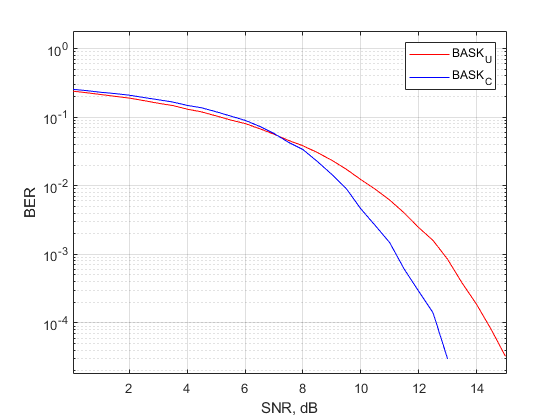

Perr = 1 - 1/2*(1 + erf(x/sqrt(2))); % Error probability for BASK modulation

figure(2);
semilogy(SNR, BERval, 'r');
grid on;
xlabel('SNR, dB');
ylabel('BER');
hold on;
semilogy(SNR, BERval11, 'b');
grid on;
xlabel('SNR, dB');
ylabel('BER');
legend('BASK_U', 'BASK_C')